# Exercises 5.5

3. The nodal coordinates of a four-node quadrilateral element are (x1,y1)  =  (0,0), (x2,y2)  =  (2,0), (x3,y3)  =  (2,2) and (x4,y4)  =  (0,2). The displacements vector for this element is shown below. Assuming full integration, find the strain and the stress vector at each integration points. Later, find the internal forces vector F(e) (nodal forces). Use E= 20GPa and ν= 0.1.U(e)=[0.0  0.0  0.001  0.0  0.002  −0.001  −0.001  −0.001]T

clear all
clc

## Material

E    = 20e6;                          % Modulo de Young [Kpa]
nu   = 0.1;                           % Poisson
q    = 4;                             % Pontos de integração
type = 4;                             % Nós por elemento
D    = E/(1-nu^2)*[1 nu 0;
                   nu 1 0;
                   0 0 (1-nu)/2];     %Matriz D

## Malha

nos = [0 0; 2 0; 2 2; 0 2];
elem = [1 2 3 4];

coor     = zeros(1, 8);     % ...
k=1;
for i = [linspace(1, 7, 4)]
    coor(:,[i i+1]) = [elem(:, k)*2-1, elem(:, k)*2]; % Matriz de coordenadas
    k=k+1;
end

## Deslocamentos sem restição

U = [0.0, 0.0, 0.001, 0.0, 0.002, -0.001, -0.001, -0.001]';     % Deslocamentos

## Gráfico

Ux = U(1:2:8);
Uy = U(2:2:8);
if type == 4
    T = 'Q4';
elseif type == 8
    T = 'Q8';
else
    T = 'Q12';
end

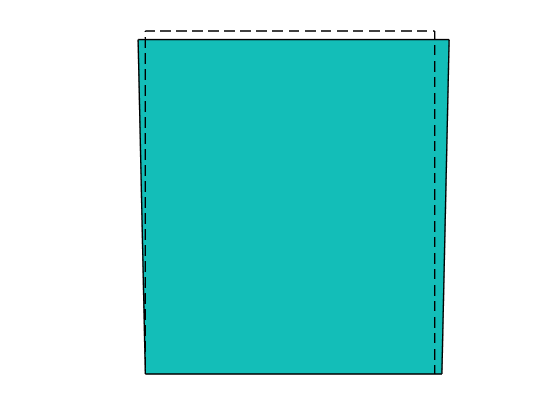

scaleFactor = 50;
figure
draw_field(nos+scaleFactor*[Ux Uy],elem,T,Ux);
draw_mesh(nos+scaleFactor*[Ux Uy],elem,T,'-');
hold on
draw_mesh(nos+scaleFactor*[Ux Uy],elem,T,'-');
draw_mesh(nos,elem,T,'--');
axis off

[f, N] = compute_F(nos, D, U, q);
F = vpa(f, 4)

$$F = \left(\begin{array}{c} -14310.0\\ 8081.0\\ 14310.0\\ 8081.0\\ 24070.0\\ -8081.0\\ -24070.0\\ -8081.0 \end{array}\right)$$

# Exercises 5.5

4. In the last exercise, recover the stress values at nodal points.

[sig] = stress_strain(nos, elem, U, D, q, coor);

sig_x  = N\sig(:,:,1)';
sig_y  = N\sig(:,:,2)';
sig_xy = N\sig(:,:,3)';
disp(vpa([sig_x sig_y sig_xy], 4))

$$\left(\begin{array}{ccc} 9091.0 & -9091.0 & -4545.0\\ 9091.0 & -9091.0 & 4545.0\\ 29290.0 & -7071.0 & 4545.0\\ 29290.0 & -7071.0 & -4545.0 \end{array}\right)$$

function [F, N] = compute_F(C, D, U, Q)
q      = quadrature(Q);
npts   = size(q, 1);
nnodes = size(C, 1);
ndof  = 2;
F      = zeros(nnodes*ndof, 1);
for i = 1:npts
xi  = q (i, 1);
eta = q (i, 2);
w   = q (i, 3);
B   = compute_B(C, Q, nnodes, ndof);
sig = D*B(:,:,i)*U;
[dN, n] = quad_shape_form(nnodes, xi, eta);
J   = C'*dN;
F   = F + B(:,:,i)'*sig*det(J)*w;
N(i,:) = n';
end
end

function [sig, eps] = stress_strain(nodes,...
    element,displacement,D,q,coordinateelem)

nodeselement= size(element, 2);
ndof        = size(nodes, 2);
numelement  = size(element, 1);
sig         = zeros(numelement, q, 3);
eps         = zeros(numelement, q, 3);
for i = 1: numelement
    C = [nodes(element(i,:), :)];
    U = displacement(coordinateelem(i,:));
    for j = 1: q
         B = compute_B(C, q, nodeselement, ndof);
         sig(i,j,:) = D*B(:,:,j)*U;
         eps(i,j,:) = B(:,:,j)*U;
    end
end
end

function B = compute_B(C, q, NoElem, ndof)
q           = quadrature(q);
Npst        = size(q, 1);
nnodes      = size(C, 1);
B           = zeros(3,nnodes*2);
for i       = 1:Npst
    xi      = q (i, 1);
    eta     = q (i, 2);
    w       = q (i, 3);
    [dN, N] = quad_shape_form(NoElem, xi, eta);
    J       = C'*dN;
    dNdX    = dN/J;
    for j = 1: nnodes
    c = (j-1) * ndof;
    b(1, c+1) = dNdX(j,1);
    b(2, c+2) = dNdX(j,2);
    b(3, c+1) = dNdX(j,2);
    b(3, c+2) = dNdX(j,1);
    end
    B(:,:,i) = b;
end
end